# Numerical simulator of fluid flow in porous media in 2D for one phase using FDM

Leonardo Arana Parodi

leonardo.arana.parodi@gmail.com

August, 2025

The main idea is to create a simple numerical reservoir simulator that solves the diffusivity equation for fluid flow in porous media in 2D. For this version, we are going to do the following steps:

- Define the equation to solve.

- Introduce the data (k, porosity, ct, viscosity, density of the water, height of the cells, number of blocks, length of each block (in x and y), total time to run the simulation and time steps duration).

- In this version, all the values of the properties introduced are constant (no variation in time or pressure).

- Use the Von Neumann stability analysis to obtain the maximum time step for an explicit method.

- Define the IC (Initial pressure for all the cells) and BC (Pressure for 2 cells or rate production/injection in 2 cells).

- Present the discretized equation using the explicit method.

- Initialize the matrices and assign the initial values.

- Calculate all the values of the blocks for each successive time step.

- Graph the values of pressure vs. time.

The ideas for the following versions are:

- Include the Crank Nicolson method as an alternative to the explicit method to use larger time steps.

- Include different methods to solve the matrices (LU factorization, Iterative methods, etc).

- Include variation of petrophysical properties as function of pressure.

- Add other phases. 

Equation to solve:


$$\frac{\partial^2 }{\partial x^2 }p+\frac{\partial^2 }{\partial y^2 }p=\frac{\phi \mu C_t }{k}\frac{\partial }{\partial t}p+\frac{q_m \mu }{k\rho }$$


Equation obtained from the book "Petroleum Reservoir Simulation" Aziz and Settari. Eq. 2.43.

Assumptions:

Constant values: porosity, viscosity, Ct, permeability and density.

Injection: $q_m$<0

Production: $q_m$>0

Units of $q_m$: $\frac{\textrm{kg}}{m^3 s}$

# 1. Input data

clc; clear; close all;
%This section can be modified with other values
%Data:
k=10*9.869233E-16; %[m^2];
mu=0.001; %[Pa*s];
ct=4.5E-10; %[1/Pa];
poro=0.2; %[dim.];
dens=1000; %[kg/m^3];
nblocks=10; %[nblocks in x and nblocks in y]...total model of nblocks by nblocks
deltax=1; %[m] length of each block;
height= 1; %[m];
time=90; %[s] time to run the simulation


vcell=deltax^2*height; %[m^3] don't touch this;

# 2. Von Neumann Stability analysis

Doing $\Delta x=\Delta y$ and calling it $\Delta h$

Equation used:


$$\textrm{Max}\;\textrm{Time}\;\textrm{step}\;\textrm{stable}=\frac{{\Delta h}^2 \phi \mu c_t }{2k}$$


Taken from the course "Numerical Methods for Engineers" of Jeffrey Chasnov (HKUST).

tstep=deltax^2*poro*mu*ct/(2*k);
if tstep>1
    tstep=1;
end
fprintf("The time step is: " + tstep +" seconds")

The time step is: 1 seconds

implicit=0;
nsteps=round(time/tstep,0);

# 3. Defining the IC and BC

## 3.1. Initial Conditions

%This section can be modified with other values
pinit=100E5; %[Pa]; IC for all the cells

## 3.2. Boundary Condition of Injection

%This section can be modified with other values
pbcinj= 200E5; %[Pa]; BC of injection for 1 cell
qbcinj=-20/(24*60*60); %[m^3/s];
cbcinjx=6; %coordinate x of injection;
cbcinjy=3; %coordinate y of injection;

## 3.3. Boundary Condition of Production

%This section can be modified with other values
pbcprd= 5E5; %[Pa]; BC of injection for 1 cell
qbcprd=15/(24*60*60); %[m^3/s];
cbcprdx=10; %coordinate x of production;
cbcprdy=10; %coordinate y of production;

### 3.4. Define the BC to use (Pressure or Rate)

%This section can be modified with other values
%Define type of BC: 0=pressure, 1=rate;
bctype=1;

# 4. Equations used for the discretization

Doing:


$$\alpha =\frac{k\Delta t}{\phi \mu c_t {\Delta h}^2 }$$


## 4.1. Explicit method

Discretized equation using the explicit method:


$${p_{i,j} }^{t+1} ={p_{i,j} }^t +\alpha *\left\lbrack {p_{i+1,j} }^t +{p_{i-1,j} }^t -4{p_{i,j} }^t +{p_{i,j+1} }^t +{p_{i,j-1} }^t \right\rbrack -\frac{q_m \Delta t}{\phi c_t \rho }$$


## 4.2. Boundary points

### Pressure


$${p_{0,j} }^t ={p_{\textrm{nblocks},j} }^t ={p_{i,0} }^t ={p_{i,\textrm{nblocks}} }^t =p_{\textrm{BC}}$$


### Rate

#### 
$${p_{0,j} }^t ={p_{1,j} }^t$$


${p_{\textrm{nblocks}+1,j} }^t$=${p_{\textrm{nblocks},j} }^t$


$${p_{i,0} }^t ={p_{i,1} }^t$$



$${p_{i,\textrm{nblocks}+1} }^t ={p_{i,\textrm{nblocks}} }^t$$


# 5. Generate the matrix of pressures and sources

p=zeros(nblocks, nblocks, nsteps);
p(:,:,1)=ones(nblocks,nblocks)*pinit; %Assign the initial pressure value to the matrix of the first time step.

Define a matrix with the sources.

s=zeros(nblocks, nblocks);
if bctype==1
    s(cbcinjx, cbcinjy)=qbcinj*tstep/(poro*vcell*ct);
    s(cbcprdx, cbcprdy)=qbcprd*tstep/(poro*vcell*ct);
end

Generate the "alpha" variable


$$\alpha =\frac{k\Delta t}{\phi \mu c_t {\Delta h}^2 }$$


alpha=k*tstep/(poro*mu*ct*deltax^2);

# 6. Explicit method

Assign the values for each block of all the other time steps (from the 2nd to the end)


$${p_{i,j} }^{t+1} ={p_{i,j} }^t +\alpha *\left\lbrack {p_{i+1,j} }^t +{p_{i-1,j} }^t -4{p_{i,j} }^t +{p_{i,j+1} }^t +{p_{i,j-1} }^t \right\rbrack -\frac{q_m \Delta t}{\phi c_t \rho }$$


if implicit==0
    for t=2:nsteps
    for i=2:(nblocks-1)
        for j=2:(nblocks-1)
            p(i,j,t)=p(i,j,t-1)+alpha*[p(i+1,j,t-1)+p(i-1,j,t-1)-4*p(i,j,t-1)+p(i,j+1,t-1)+p(i,j-1,t-1)];
        end
    end
    %Fill the first column
    for i=2:(nblocks-1)
        p(i,1,t)=p(i,1,t-1)+alpha*[p(i+1,1,t-1)+p(i-1,1,t-1)-4*p(i,1,t-1)+p(i,2,t-1)+p(i,1,t-1)];
    end

    %Fill the last column
    for i=2:(nblocks-1)
        p(i,nblocks,t)=p(i,nblocks,t-1)+alpha*[p(i+1,nblocks,t-1)+p(i-1,nblocks,t-1)-4*p(i,nblocks,t-1)+p(i,nblocks,t-1)+p(i,nblocks-1,t-1)];
    end
    
    %Fill the first row
    for j=2:(nblocks-1)
        p(1,j,t)=p(1,j,t-1)+alpha*[p(2,j,t-1)+p(1,j,t-1)-4*p(1,j,t-1)+p(1,j+1,t-1)+p(1,j-1,t-1)];
    end

    %Fill the last row
    for j=2:(nblocks-1)
        p(nblocks,j,t)=p(nblocks,j,t-1)+alpha*[p(nblocks,j,t-1)+p(nblocks-1,j,t-1)-4*p(nblocks,j,t-1)+p(nblocks,j+1,t-1)+p(nblocks,j-1,t-1)];
    end
    %Fill the (1,1) corner
    p(1,1,t)=p(1,1,t-1)+alpha*[p(2,1,t-1)+p(1,1,t-1)-4*p(1,1,t-1)+p(1,2,t-1)+p(1,1,t-1)];
    %Fill the (1,nblocks) corner
    p(1,nblocks,t)=p(1,nblocks,t-1)+alpha*[p(1,nblocks,t-1)+p(1,nblocks,t-1)-4*p(1,nblocks,t-1)+p(1,nblocks,t-1)+p(1,nblocks-1,t-1)];
    %Fill the (nblocks,1) corner
    p(nblocks,1,t)=p(nblocks,1,t-1)+alpha*[p(nblocks,1,t-1)+p(nblocks-1,1,t-1)-4*p(nblocks,1,t-1)+p(nblocks,2,t-1)+p(nblocks,1,t-1)];
    %Fill the (nblocks, nblocks) corner
    p(nblocks,nblocks,t)=p(nblocks,nblocks,t-1)+alpha*[p(nblocks,nblocks,t-1)+p(nblocks-1,nblocks,t-1)-4*p(nblocks,nblocks,t-1)+p(nblocks,nblocks,t-1)+p(nblocks,nblocks-1,t-1)];
    
    %Adding the BC defined:
    if bctype==0
        p(cbcinjx, cbcinjy,t)=pbcinj;
        p(cbcprdx, cbcprdy,t)=pbcprd;
    else

        p(:,:,t)=p(:,:,t)-s; %Adding the source:
    end
    end
end

# 7. Graphs

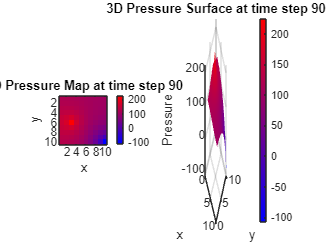

p_bar=p./100000;

[Nx, Ny, Nt] = size(p_bar);


x = 1:Nx;
y = 1:Ny;
[X, Y] = meshgrid(y, x);   


fig = figure;
cmap = [linspace(0,1,256)', zeros(256,1), linspace(1,0,256)'];

for t = 1:Nt
    % Subplot 1: 2D colormap
    subplot(1,2,1);
    imagesc(x, y, p_bar(:,:,t));
    axis equal tight;
    colormap(cmap); 
    colorbar;
    title(['2D Pressure Map at time step ', num2str(t)]);
    xlabel('x');
    ylabel('y');
    
    % Subplot 2: 3D surface
    subplot(1,2,2);
    surf(X, Y, p_bar(:,:,t));
    shading interp;
    colormap(cmap); 
    colorbar;
    title(['3D Pressure Surface at time step ', num2str(t)]);
    xlabel('x');
    ylabel('y');
    zlabel('Pressure');
    view(45,30);  % angle
    
    drawnow;
    
    
    pause(0.5);
end